## CP 3.3

clear; clc;
%H(z) = z^-1+z^-2 / 1-0.9z^-1+0.81z^-2

b = [0 1 1];    
a = [1 -0.9 0.81]; 
LHS = sprintf('y(n) = %.1f * y(n-1) - %.2f * y(n-2)', -a(2), -a(3));
RHS = sprintf(' + %.0f * x(n-1) + %.0f * x(n-2)', b(2), b(3));
disp('The difference equation is:')

The difference equation is:


disp([LHS, RHS])

y(n) = 0.9 * y(n-1) - -0.81 * y(n-2) + 1 * x(n-1) + 1 * x(n-2)


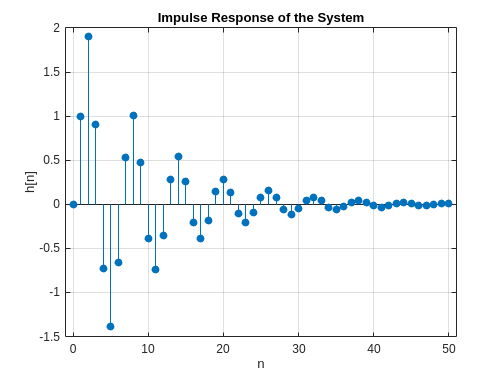


N = 50;
x = [1, zeros(1,N)]; 
h = filter(b, a, x);
n = 0:N;
figure(1);
stem(n, h, 'filled');
xlabel('n');
ylabel('h[n]');
title('Impulse Response of the System');
grid on;

## CP 3.5

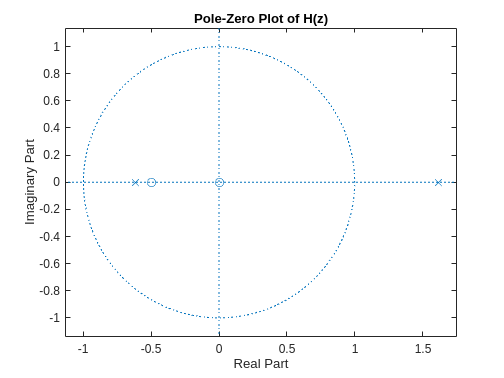

clear; clc;
b = [2 1];      
a = [1 -1 -1]; 

figure;
zplane(b,a); 
title('Pole-Zero Plot of H(z)');


poles = roots(a);
zero = roots(b);
disp('Poles:');  disp(poles);

Poles:
   -0.6180
    1.6180



disp('Zeros:'); disp(zero);

Zeros:
   -0.5000



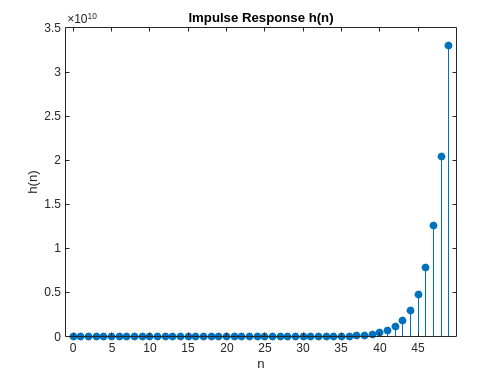


N = 50;
x = [1; zeros(N-1,1)];
h = filter(b,a,x);
figure(2);
stem(0:N-1, h, 'filled');
title('Impulse Response h(n)');
xlabel('n'); ylabel('h(n)');